# Inertia properties of a 2 blade propeller

## What we're going to do:

In this FAQ, we're going to explore the inertia properties of a 2 bladed propeller.  We'll approximate the propeller by a rectangular plate

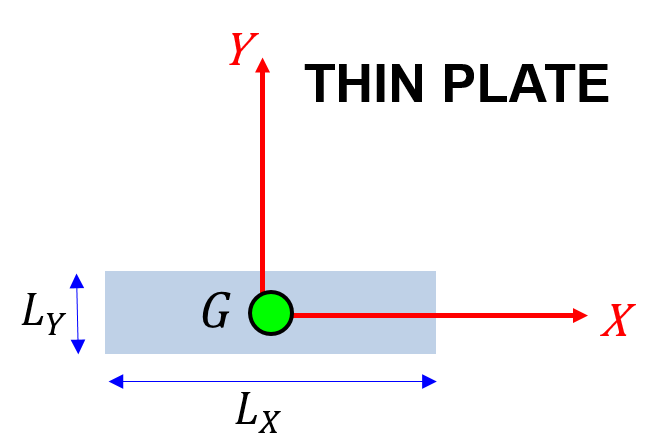

**WHY are we doing this?**

$\bullet$ explore how the inertia matrix (relative to the XY-frame) changes as the propeller spins

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Consider a thin Rectangular plate:

  

In this figure we have a G-frame attached to the Centre of mass of the plate, Let's calculate the inertia of the plate about this G-frame

syms Lx Ly m

% create an instance of a thin rectangular plate class
TRP_OBJ = inertia_thin_rect_plate_CLS(Lx, Ly, m);

% look at the Inertia matrix for the G-frame
I_LOCAL = TRP_OBJ.get_I()

$$I\_LOCAL = \left(\begin{array}{ccc} \frac{{\mathrm{Ly}}^{2}\,m}{12} & 0 & 0\\ 0 & \frac{{\mathrm{Lx}}^{2}\,m}{12} & 0\\ 0 & 0 & \frac{m\,\left({\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{12} \end{array}\right)$$

## Consider an arbitrarily orientated propeller:

Consider the following arbitrarily orientated propeller system:

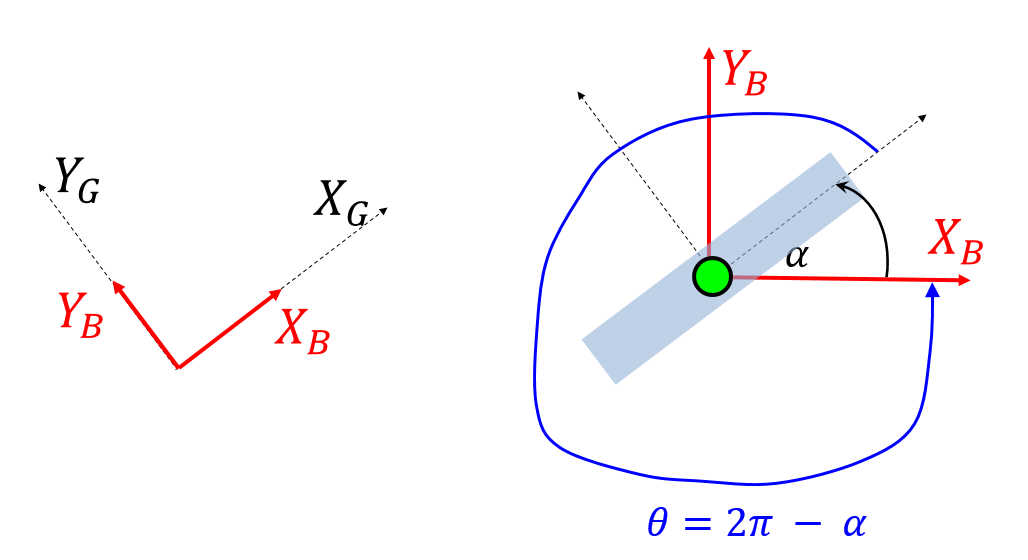

% create a PASSIVE rotation object
syms alpha
BLUE_OBJ  = bh_rot_passive_G2B_CLS({'D1Z'}, [ (2*pi - alpha) ], 'SYM');

% extract the PASIVE rotation matrix bRg
BLUE_bRg = BLUE_OBJ.get_R1

$$BLUE\_bRg = \left(\begin{array}{ccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% calculate the inertias relative to the XB,YB frame
gI = I_LOCAL;
bRg = BLUE_bRg;
Ib_blade  = bRg * gI * bRg.'

$$Ib\_blade = \begin{array}{l} \left(\begin{array}{ccc} \frac{m\,{\mathrm{Lx}}^{2}\,{\sin\left(\alpha \right)}^{2}}{12}+\frac{m\,{\mathrm{Ly}}^{2}\,{\cos\left(\alpha \right)}^{2}}{12} & \sigma_{1} & 0\\ \sigma_{1} & \frac{m\,{\mathrm{Lx}}^{2}\,{\cos\left(\alpha \right)}^{2}}{12}+\frac{m\,{\mathrm{Ly}}^{2}\,{\sin\left(\alpha \right)}^{2}}{12} & 0\\ 0 & 0 & \frac{m\,\left({\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{12} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{Ly}}^{2}\,m\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)}{12}-\frac{{\mathrm{Lx}}^{2}\,m\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)}{12} \end{array}$$

## Let's plot how the these terms vary with alpha.

substitute numeric values for Lx and Ly and mass

Lx_num = 1;
Ly_num = 0.1;
m_num = 1;
I_LOCAL_num = subs(I_LOCAL, [Lx, Ly, m], [Lx_num, Ly_num, m_num])

$$I\_LOCAL\_num = \left(\begin{array}{ccc} \frac{1}{1200} & 0 & 0\\ 0 & \frac{1}{12} & 0\\ 0 & 0 & \frac{101}{1200} \end{array}\right)$$

Ib_blade_num = subs(Ib_blade, [Lx, Ly, m], [Lx_num, Ly_num, m_num])

$$Ib\_blade\_num = \left(\begin{array}{ccc} \frac{{\cos\left(\alpha \right)}^{2}}{1200}+\frac{{\sin\left(\alpha \right)}^{2}}{12} & -\frac{33\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)}{400} & 0\\ -\frac{33\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)}{400} & \frac{{\cos\left(\alpha \right)}^{2}}{12}+\frac{{\sin\left(\alpha \right)}^{2}}{1200} & 0\\ 0 & 0 & \frac{101}{1200} \end{array}\right)$$

OK: now let's calculate the inertia matrix for different values of $\alpha$

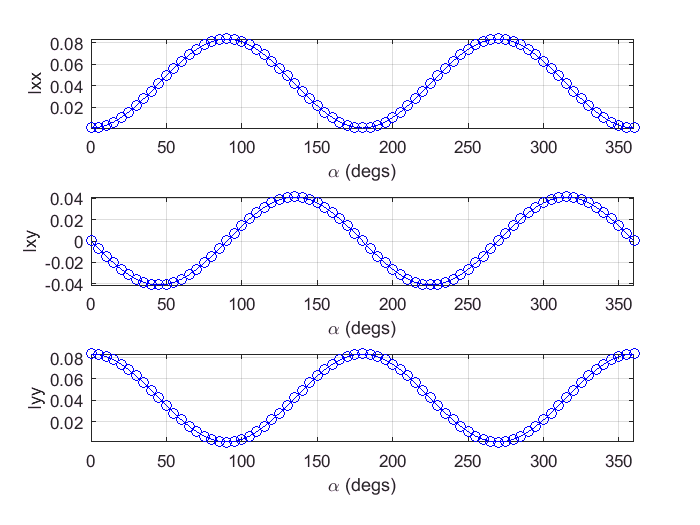

alpha_deg_num = [0:5:360];
alpha_rad_num = (pi/180)*alpha_deg_num;
for kk=1:length(alpha_rad_num)
    alpha_num = alpha_rad_num(kk);
    tmp_I     =  subs(Ib_blade_num, alpha, alpha_num);
    
    bh.Ixx(kk) = tmp_I(1,1);
    bh.Iyy(kk) = tmp_I(2,2);
    bh.Ixy(kk) = tmp_I(1,2);
end

% OK plot it
figure
subplot(3,1,1);
   plot(alpha_deg_num, bh.Ixx, 'ob-'); 
        axis('tight'); grid('on'); xlabel('\alpha (degs)'); ylabel('Ixx');
subplot(3,1,2);
   plot(alpha_deg_num, bh.Ixy, 'ob-'); 
        axis('tight'); grid('on'); xlabel('\alpha (degs)'); ylabel('Ixy');
subplot(3,1,3);
   plot(alpha_deg_num, bh.Iyy, 'ob-'); 
   axis('tight'); grid('on'); xlabel('\alpha (degs)'); ylabel('Iyy');

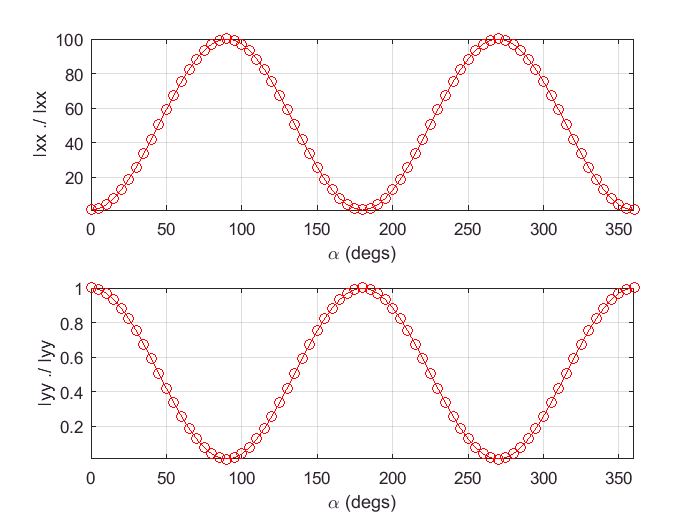

   
% OK plot the terms normalised by the local pose inertias
figure
subplot(2,1,1);
   plot(alpha_deg_num, bh.Ixx/I_LOCAL_num(1,1), 'or-'); 
        axis('tight'); grid('on'); xlabel('\alpha (degs)'); ylabel('Ixx ./ Ixx');
subplot(2,1,2);
   plot(alpha_deg_num, bh.Iyy/I_LOCAL_num(2,2), 'or-'); 
   axis('tight'); grid('on'); xlabel('\alpha (degs)'); ylabel('Iyy ./ Iyy');